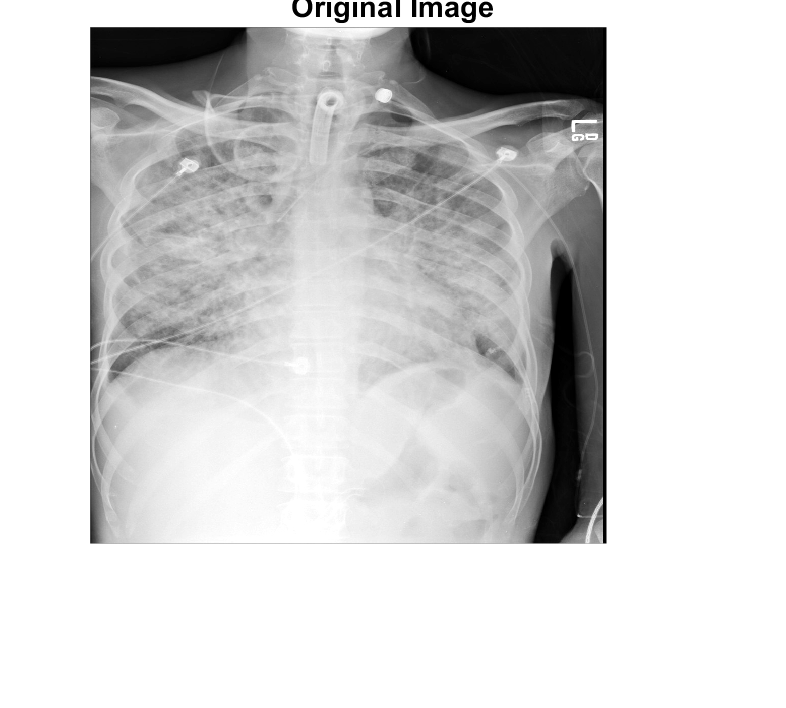


clc; clear; close all;

%%Create Data Stores
d1 = "stage_2_train_images/Positive/";
Pfiles = dir(fullfile(d1));
Pfiles([Pfiles.isdir]) = [];
n_Pfiles = length(Pfiles);

d2 = "stage_2_train_images/Negative/";
Nfiles = dir(fullfile(d2));
Nfiles([Nfiles.isdir]) = [];
n_Nfiles = length(Nfiles);

for i = 2:2
    filename = fullfile(d1, Pfiles(i).name);
    hold on
    % Read file and gray scale
%     figure;
    img = dicomread(filename);
    img = im2gray(img);
    img = imadjust(img);
    imshow(img)
    title("Original Image");
end

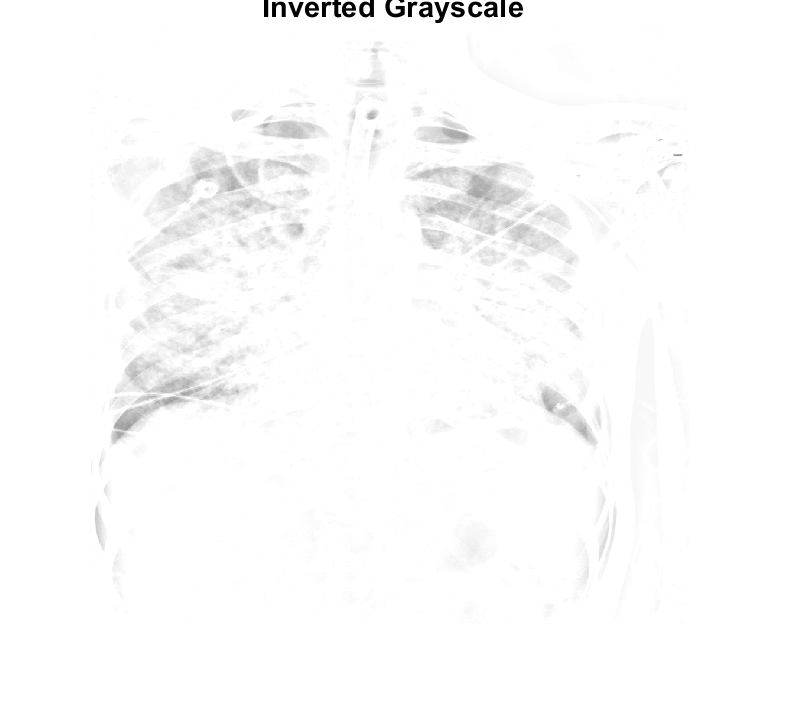

    % Sharpening
%     img_sharp = imsharpen(img);
%     imshow(img_sharp)
%     title("Sharp Image");
    
    testimg = 255 - img;
    testimg_clear = imclearborder(testimg);
    testimg_clear_inv = 255-testimg_clear;
    imshow(testimg_clear_inv)
    title("Inverted Grayscale");

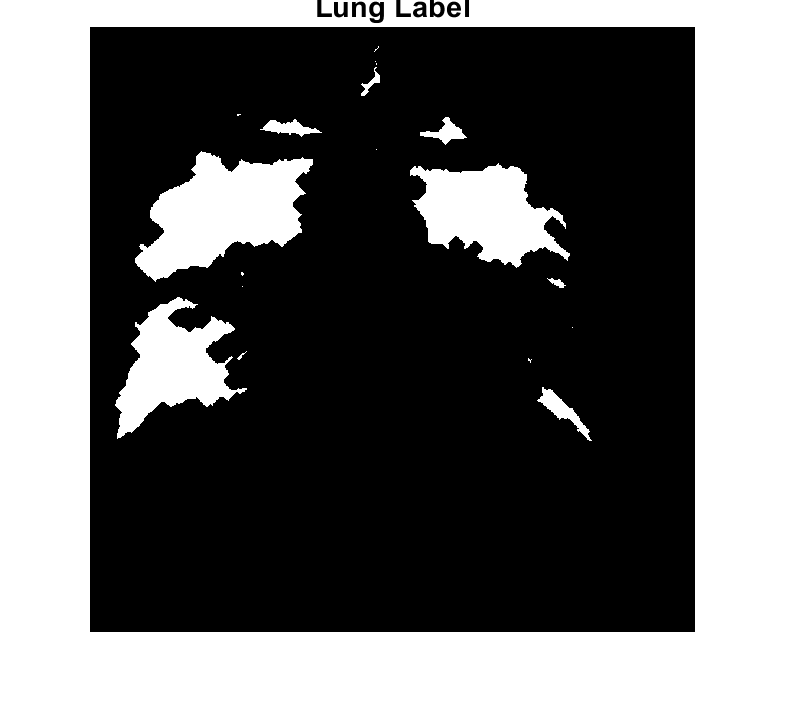

% Find lungs
I = testimg_clear_inv;
[BW, thresh] = edge(I,'sobel');
fudgeFactor = 0.8;
Iedge = edge(I,'sobel',fudgeFactor*thresh);
% imshow(Iedge)

se90 = strel('line',6,90);
se0 = strel('line',3,0);
Idilate = imdilate(Iedge,[se90, se0]);
% imshow(Idilate)

Ifill = imfill(Idilate, 'holes');
% imshow(Ifill)

seD = strel('diamond', 3);
Ierode1 = imerode(Ifill,seD);
Ierode2 = imerode(Ierode1,seD);
Ierode3 = imerode(Ierode2,seD);
Ifinal = imerode(Ierode3,seD);
imshow(Ifinal)
title('Lung Label')

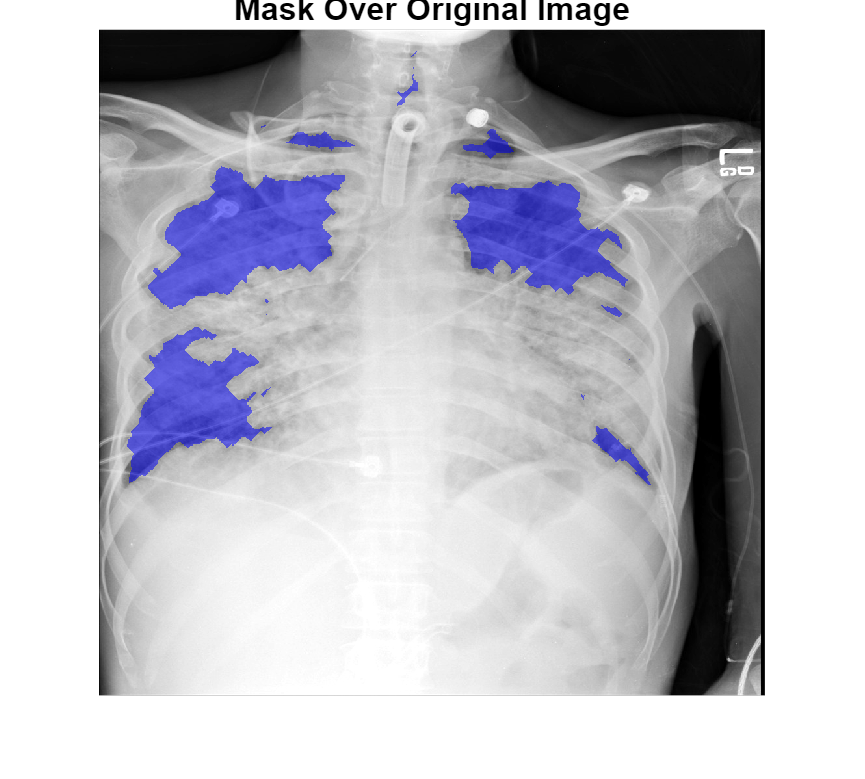


imshow(labeloverlay(img,Ifinal))
title('Mask Over Original Image')

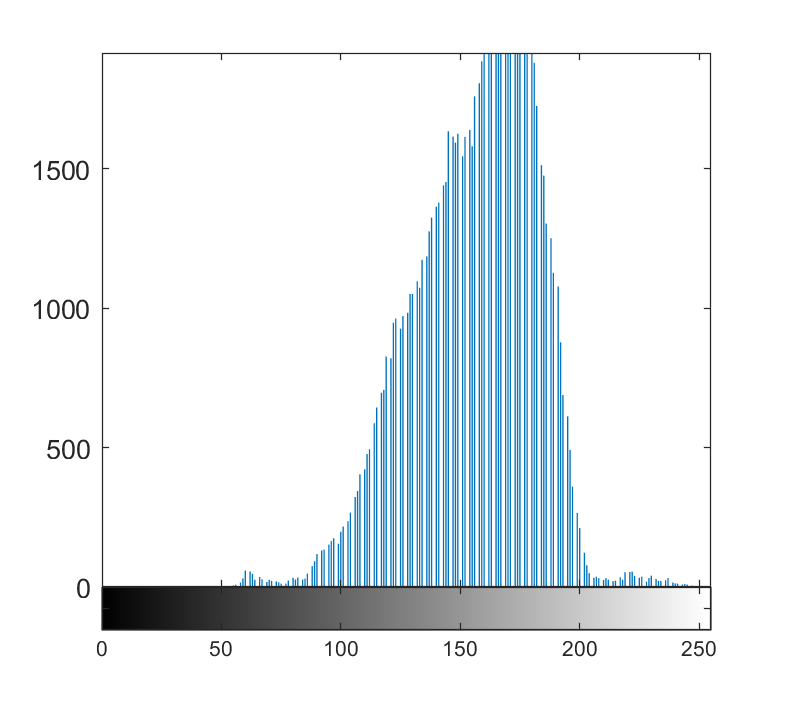


imhist(img(find(Ifinal==1)))


%creating the table output
    %Labels array
    pos_label = strings(n_Pfiles,1);
    pos_label(1:end) = "positive";
    neg_label = strings(n_Nfiles,1);
    neg_label(1:end) = "negative";
    labels = [pos_label;neg_label];

labels = 55×1 string array
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "positive"
    "negative"
    "negative"
    "negative"
    "negative"
    "negative"



    %First variable array
    var1 = zeros(size(labels));

    %Second variable array
    var2 = zeros(size(labels));

    %Table
    Model_Table = table(labels,var1,var2)

Model_Table = 55×3 table
      labels      var1    var2
    __________    ____    ____

    "positive"     0       0  
    "positive"     0       0  
    "positive"     0       0  
    "positive"     0       0  
    "positive"     0       0  
    "positive"     0       0  
    "positive"     0       0  
    "positive"     0       0  
    "positive"     0       0  
    "positive"     0       0  
    "positive"     0       0  
    "positive"     0       0  
    "positive"     0       0  
    "positive"     0       0  
    "positive"     0       0  
    "positive"     0       0  
